# Questions:

**Q. Plot the following in axis range -> [-6 6 -3 3]:**


$$x=\mathrm{acos}\left(t\right)-\frac{{\mathrm{asin}}^2 t}{\sqrt[\;]{2}}$$



$$y=\mathrm{acos}\left(t\right)\mathrm{sin}\left(t\right)$$


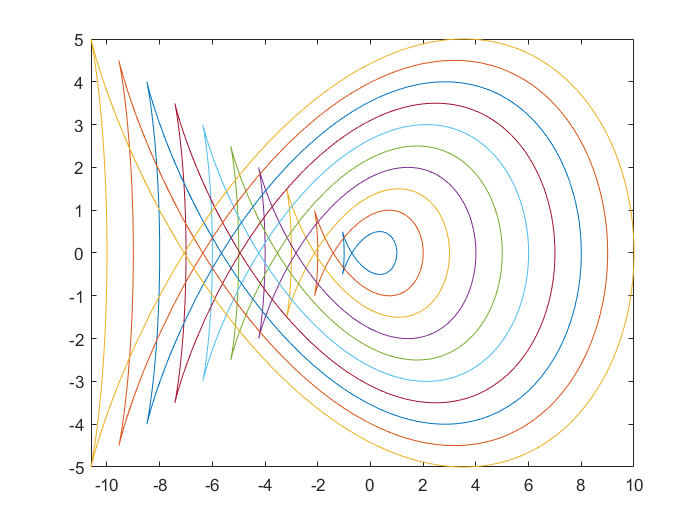

syms t 
axis([-6 5 -5 5]);
for a = 1:10
    x(t) = a*cos(t)-(a*(sin(t))^2)/sqrt(2);
    y(t) = a*cos(t)*sin(t);
    fplot(x(t),y(t))
    hold on
end
hold off

**2.1**

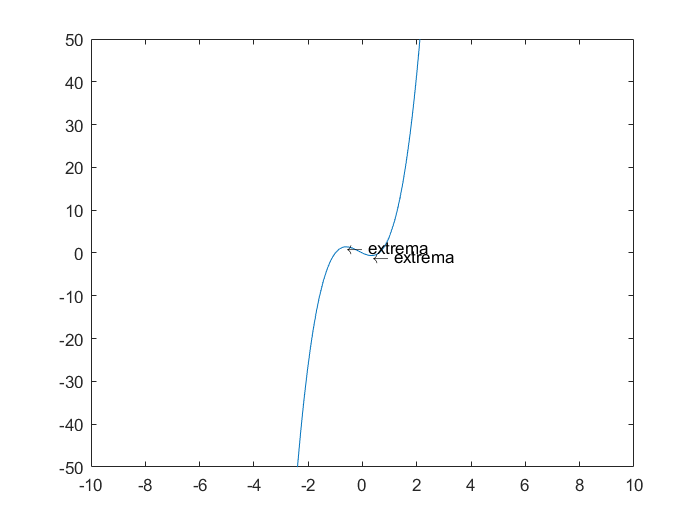

syms x
y(x) = 5*x^3 + 2*x^2 - 3*x;
y1 = diff(y);
xcoordinate = solve(y1==0);
ycoordinate = y(xcoordinate);
fplot(y(x));
axis([-10 10 -50 50]);
text(xcoordinate,ycoordinate,'\leftarrow extrema')

**2.2**

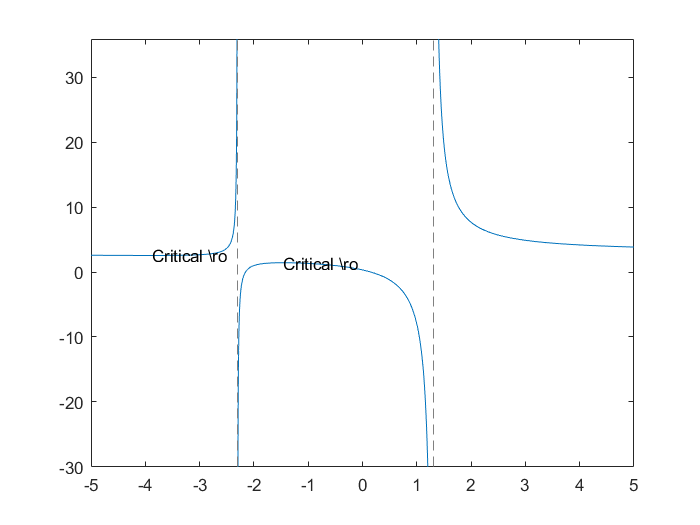

syms x
num = (3*x^2 + 6*x -1);
den = (x^2 + x -3);
f(x) = num / den;
vertical = limit(f(x), inf);
horizontal = solve(den==0);
fplot(f(x));
% Finding maxima and minima
y1 = diff(f(x));
x = vpasolve(y1 == 0);
y = f(x);
for i = 1:length(x)
    text(x(i),y(i),'Critical');
end